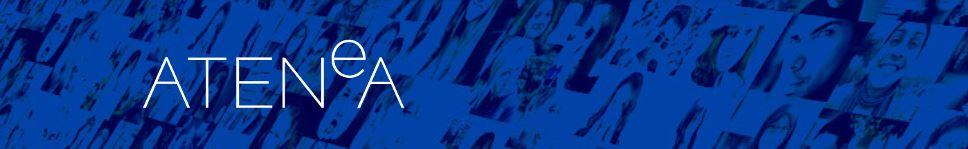

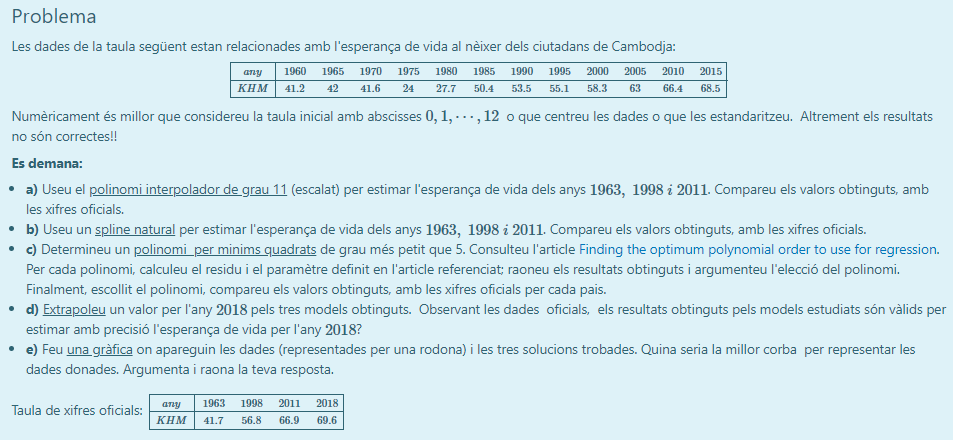

## Pràctica 2

clearvars
format shortG
x = 0:11;
y = [41.2 42 41.6 24 27.7 50.4 53.5 55.1 58.3 63 66.4 68.5];
% Relació: un any -> 0.2
% Per tant: 1963 -> 0.6, 1998 -> 7.6, 2011 -> 10.2, 2018 -> 11.6

`(a)`

% Polinomi interpolador
v1_1963 = round(polyinterp(x,y,0.6),1); er1_1963 = abs(41.7-v1_1963);
v1_1998 = round(polyinterp(x,y,7.6),1); er1_1998 = abs(56.8-v1_1998);
v1_2011 = round(polyinterp(x,y,10.2),1); er1_2011 = abs(66.9-v1_2011);
R = [v1_1963, 41.7,er1_1963; v1_1998, 56.8, er1_1998; v1_2011, 66.9, er1_2011];
T = array2table(R,'RowNames',{'1963','1998','2011'},'VariableNames',{'KHM estimació','KHM oficial','error'}); disp(T)

            KHM estimació    KHM oficial    error
            _____________    ___________    _____

    1963        72.9            41.7        31.2 
    1998          58            56.8         1.2 
    2011        53.5            66.9        13.4 



`(b)`

% Spline natural
v2_1963 = round(interp1(x,y,0.6,'spline'),1); er2_1963 = abs(41.7-v2_1963);
v2_1998 = round(interp1(x,y,7.6,'spline'),1); er2_1998 = abs(56.8-v2_1998);
v2_2011 = round(interp1(x,y,10.2,'spline'),1); er2_2011 = abs(66.9-v2_2011);
R = [v2_1963, 41.7,er2_1963; v2_1998, 56.8, er2_1998; v2_2011, 66.9, er2_2011];
T = array2table(R,'RowNames',{'1963','1998','2011'},'VariableNames',{'KHM estimació','KHM oficial','error'}); disp(T)

            KHM estimació    KHM oficial    error
            _____________    ___________    _____

    1963          40            41.7         1.7 
    1998        56.8            56.8           0 
    2011        66.9            66.9           0 



`(c)`

% Trobant l'ordre òptim del polinomi
[sr(1), var(1)] = sr_var_values(x,y,1); [sr(2), var(2)] = sr_var_values(x,y,2);
[sr(3), var(3)] = sr_var_values(x,y,3); [sr(4), var(4)] = sr_var_values(x,y,4);
[sr(5), var(5)] = sr_var_values(x,y,5);
T = array2table([[1:5]',round(sr,1)',round(var,1)'],'VariableNames',{'Order poly','Sr(m)','Sr(m)/(n-m-1)'}); disp(T)

    Order poly    Sr(m)    Sr(m)/(n-m-1)
    __________    _____    _____________

        1         766.4        76.6     
        2         600.6        66.7     
        3         397.9        49.7     
        4         397.2        56.7     
        5         287.2        47.9     



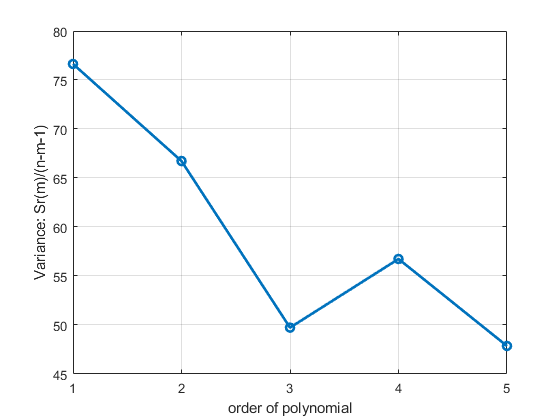

plot(1:5,var,'-o','LineWidth',2)
grid on
ylabel('Variance: Sr(m)/(n-m-1)')
xlabel('order of polynomial')
xticks([1:5])

% Observant la gràfica i els resultats veiem que els millors ordres de
% polinomi són el 3 i el 5. Escolleixo el 3 ja que es més sencill de
% calcular computacionalment.

% Polinomi per minims quadrats
pol = polyfit(x,y,3);
v3_1963 = round(polyval(pol,0.6),1); er3_1963 = abs(41.7-v3_1963);
v3_1998 = round(polyval(pol,7.6),1); er3_1998 = abs(56.8-v3_1998);
v3_2011 = round(polyval(pol,10.2),1); er3_2011 = abs(66.9-v3_2011);
v3_2018 = round(polyval(pol,11.6),1); er3_2018 = abs(69.6-v3_2018);
R = [v3_1963, 41.7, er3_1963; v3_1998, 56.8, er3_1998; v3_2011, 66.9, er3_2011; v3_2018, 69.6, er3_2018];
T = array2table(R,'RowNames',{'1963','1998','2011','2018'},'VariableNames',{'KHM estimació','KHM oficial','error'}); disp(T)

            KHM estimació    KHM oficial    error
            _____________    ___________    _____

    1963        39.5            41.7         2.2 
    1998        58.1            56.8         1.3 
    2011        67.6            66.9         0.7 
    2018        65.1            69.6         4.5 



`(d)`

% Extrapolació any 2018
% 1. Polinomi interpolador
% 2. Spline natural
% 3. Polinomi per minims quadrats
v1_2018 = round(polyinterp(x,y,11.6),1); er1_2018 = abs(69.6-v1_2018);
v2_2018 = round(interp1(x,y,11.8,'spline'),1); er2_2018 = abs(69.6-v2_2018);
R = [69.6, 0; v1_2018, er1_2018; v2_2018, er2_2018; v3_2018, er3_2018];
T = array2table(R,'RowNames',{'KHM_oficial','polyinterp','spline natural','minim quadrats'},'VariableNames',{'KHM','error'}); disp(T)

                       KHM      error 
                      ______    ______

    KHM_oficial         69.6         0
    polyinterp        1313.3    1243.7
    spline natural      69.9       0.3
    minim quadrats      65.1       4.5



% Com era de esperar, el polinomi interpolador no serveixen per estimar
% fora del rang, i això ens dona un error exageradament gran. En canvi,
% spline natural i minim quadrats s'apropen bastant a les dades oficials, i
% es podrien considerar vàlides, sobretot spline natural. Si hagués de fer
% un estudi escolliria spline natural.

`(e)`

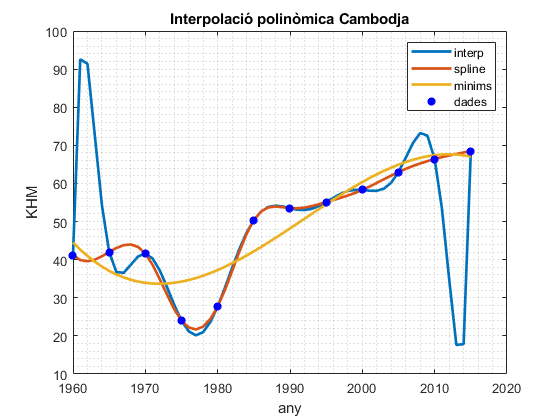

ex = [1960:2015];
z = [0:0.2:11];
pi = polyinterp(x,y,z);
sn = interp1(x,y,z,'spline');
pol = polyfit(x,y,3); mq = polyval(pol,z);
plot(ex,pi,ex,sn,ex,mq,[1960:5:2015],y,'*b','LineWidth',2)
grid minor
ylabel('KHM'), xlabel('any'), legend('interp','spline','minims','dades')
title('Interpolació polinòmica Cambodja')

% Observant el gràfic podem observar com la interpolació polinòmica obté
% bons resultats en les dades cetnrades, però a les puntes es dispara molt
% donant resultats gens bons. Per altre banda minims quadrats fluixeja en
% algunes representacions de les dades. I finalment, spline natural es la
% corba que millor representa les dades. Per tant, si hi ha que escollir
% alguna, spline natural és la més encertada.

function [sr,var] = sr_var_values(x,y,n)
pol = polyfit(x,y,n); z = polyval(pol,x);
err = abs(y-z);
sr = sum(err.^2);
var = sr/(length(x)-n-1);
end
% ---------------------------------------------
function v = polyinterp(x,y,u)
%POLYINTERP  Polynomial interpolation.
%   v = POLYINTERP(x,y,u) computes v(j) = P(u(j)) where P is the
%   polynomial of degree d = length(x)-1 with P(x(i)) = y(i).

%   Copyright 2014 Cleve Moler
%   Copyright 2014 The MathWorks, Inc.

% Use Lagrangian representation.
% Evaluate at all elements of u simultaneously.

n = length(x);
v = zeros(size(u));
for k = 1:n
   w = ones(size(u));
   for j = [1:k-1 k+1:n]
      w = (u-x(j))./(x(k)-x(j)).*w;
   end
   v = v + w*y(k);
end
end